# TGN Colocalization Analysis

This code, imports the images of HA at the plasma membrane (_PM), the tight junctions ZO-1 (_TJ), HA at the Golgi (_G), the GM130 signal (_GM130). They must have been splitted and converted into .tiff beforehand, and they must contain the previously mentioned endings. 

A mask of the TGN is performed from the TGN46 image with an intensity threshold. This mask is used for the quantification of fluorescence intensity. This intensity is normalized to the px area. In the case of the Golgi plane, it calculates the intensity within the TGN regions and is normalized to the TGN pixel area. In the case of the PM image, it is calculated by the intensity of the whole cell, devided by the px area of the whole cell. 

## Data organization

In this section, one selects the full list of tiff files for a certain condition. All the image paths are ordered by sets (rows). In the first column one finds all TGN46 channel images, in the second column the HA in the Golgi plane images, and in the third, all the HA in the PM images. 

[filename,path] = uigetfile('*.*','All Files (*.*)',...
                'Select files','MultiSelect','on');
path = string(path) + string(filename); %final string with the path
n_img = length(filename);
%% We classify each image by sample 
for i = 1:n_img
    name = split(filename{i},'.');
    name = name{1};
    name = split(name,'_');
    g = name{end-1}; %cell of character vectors
    groups{i} = g;
end
groups = unique(groups); % sets of images of the same field of view
files = cell(length(groups),4);
% and by channel with the last characters (_X)
for i = 1:n_img
    name = split(filename{i},'.');
    name = name{1};
    name = split(name,'_');
    clas = string(name{end}); %cell of strings
    im = string(name{end-1});
    c = find(strcmp(groups, im));
    if clas(1,1) == "G"
        files{c,2} = path{i};
    elseif clas(1,1) == "GM130"
        files{c,1} = path{i};
    elseif clas(1,1) == "PM"
        files{c,3} = path{i};
    elseif clas(1,1) == "TJ"
        files{c,4} = path{i};
    end
end
clearvars c clas filename i name path g index im

## Cell segmentation

Execute this section, if you want to segment cells by hand. 

n_sets = height(files);
cell_rois = cell(1,n_sets);
for i = 1:n_sets
    % Import images
    warning('off','all')
    ImageDataStore = datastore(files{i,4},'ReadFcn',@imfinfo);
    data = readall(ImageDataStore);
    image_w = data{1,1}.Width;
    image_h = data{1,1}.Height;
    BitDepth = data{1,1}.BitDepth;
    if BitDepth == 8
        image_i = zeros(image_h,image_w,'uint8');
    elseif BitDepth == 16
        image_i = zeros(image_h,image_w,'uint16');
    else
        image_i = zeros(image_h,image_w,'double');
    end
    tstack  = Tiff(files{i,4},'r'); % read tiff file from pathway
    image_i  = tstack.read(); %creates empty matrix with the image properties
    image_i = imadjust(image_i); %adjustes intensity range
    image_i = uint8(image_i/256); %converts it to 8 bit
    tstack  = Tiff(files{i,1},'r');
    image_2 = tstack.read(); 
    image_2 = imadjust(image_2); %adjustes intensity range
    image_2 = uint8(image_2/256); %converts it to 8 bit
    %% Colored image
    redChannel = image_i;
    greenChannel = image_2;
    blueChannel = zeros(image_h,image_w,'uint16');
    % Concatenate r, g, and b channels to form RGB image
    rgbImage = cat(3, redChannel, greenChannel, blueChannel);
    %% Represent
    set(gcf,'Visible','on')
    imshow(rgbImage(:,:,:))
    for j = 1:20
        try
            roi = drawpolygon('FaceAlpha',0,'Deletable',0,'InteractionsAllowed','none','LineWidth',1,'Color','r',...
             'DrawingArea',[0,0,image_w,image_h]);
            if length(roi.Position) > 2
                cell_rois{i}{1,j} = roi.Position;
                area = polyarea(roi.Position(:,1),roi.Position(:,2));
                cell_rois{i}{2,j} = area;
            end
        catch
            break
        end
    end
    log = cellfun(@isempty,cell_rois{1,i}(1,:));
    cell_rois{1,i}(:,log) = []; %in case some cell was not saved
end

Index in position 1 exceeds array bounds.

Example of cell rois: 

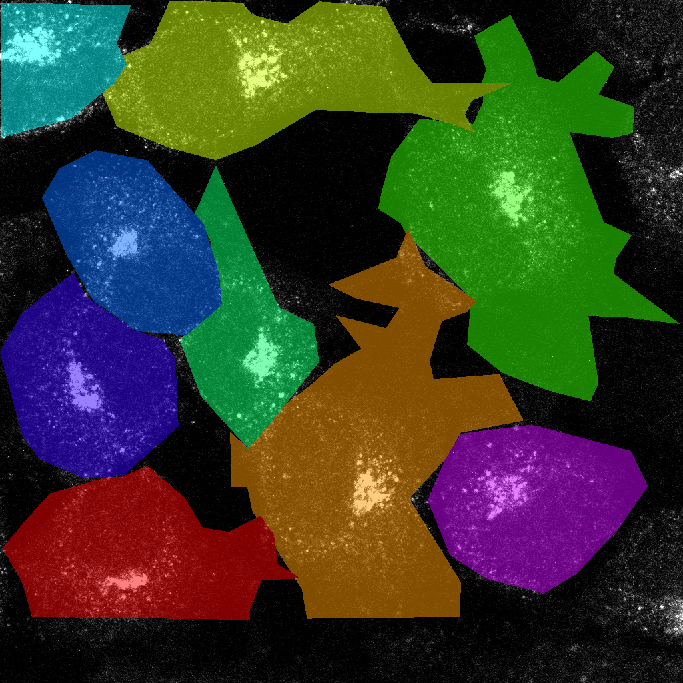

%% Import the images of one set
warning('off','all')
ImageDataStore = datastore(files{i,1},'ReadFcn',@imfinfo);
data = readall(ImageDataStore);
image_w = data{1,1}.Width;
image_h = data{1,1}.Height;
BitDepth = data{1,1}.BitDepth;
if BitDepth == 8
    image = zeros(image_h,image_w,'uint8');
elseif BitDepth == 16
    image = zeros(image_h,image_w,'uint16');
else
    image = zeros(image_h,image_w,'double');
end
tstack  = Tiff(files{i,1},'r'); % read tiff file from pathway
image(:,:)  = tstack.read(); % creates empty matrix with the image properties
warning('on','all')
image = imadjust(image); %adjustes intensity range
image = uint8(image/256);
%Get label matrix
vertices = cell(1,width(cell_rois{1,i}));
for j = 1:width(cell_rois{1,i})
    vertices{1,j} = cell_rois{1,i}{1,j};
end
n_roi = width(vertices);
L = poly2label(vertices,[1:n_roi],[image_w,image_h]);
I2 = labeloverlay(image(:,:),L,'Colormap','hsv');
imshow(I2)

## Cell segmentation

Execute this section, if you want to segment witht the tight junction channel. 

n_sets = height(files);
cell_rois = cell(1,n_sets);
for i = 1:n_sets
    %Import tight junction channel image
    warning('off','all')
    ImageDataStore = datastore(files{i,4},'ReadFcn',@imfinfo);
    data = readall(ImageDataStore);
    image_w = data{1,1}.Width;
    image_h = data{1,1}.Height;
    BitDepth = data{1,1}.BitDepth;
    if BitDepth == 8
        image = zeros(image_h,image_w,'uint8');
    elseif BitDepth == 16
        image = zeros(image_h,image_w,'uint16');
    else
        image = zeros(image_h,image_w,'double');
    end
    tstack  = Tiff(files{i,4},'r'); % read tiff file from pathway
    image(:,:)  = tstack.read(); % creates empty matrix with the image properties
    warning('on','all')
    %% Morfological operations
    I = imadjust(image);
    K = wiener2(I,[10 10]);
    I2 = imtophat(K, strel('disk', 15));
    I3 = imhmin(I2,3000); %height threshold for suppressing shallow minima
    L = watershed(I3);
    %O = labeloverlay(I(:,:),L,'Colormap','hsv');
    n_roi = max(L,[],"all");
    c = 0;
    for j = 1:n_roi
        bw = L == j;
        roi = bwboundaries(bw);
        area = polyarea(roi{1,1}(:,1),roi{1,1}(:,2));
        if area < 50000 & area > 1000 %area in pixels 
            c = c + 1;
            cell_rois{i}{1,c} = roi{1,1};
            cell_rois{i}{2,c} = area;
        end
    end
end

Representation of some example: 

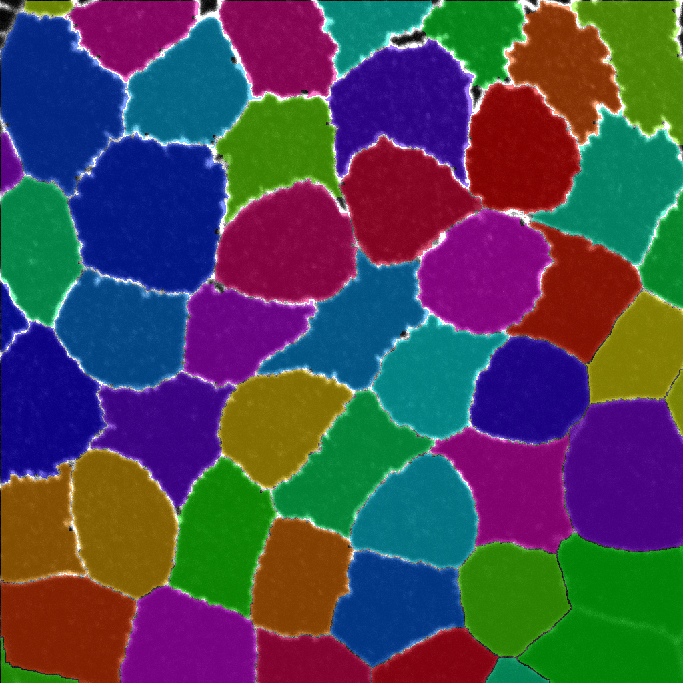

i = 3;
%% Import the images of one set
warning('off','all')
ImageDataStore = datastore(files{i,4},'ReadFcn',@imfinfo);
data = readall(ImageDataStore);
image_w = data{1,1}.Width;
image_h = data{1,1}.Height;
BitDepth = data{1,1}.BitDepth;
if BitDepth == 8
    image = zeros(image_h,image_w,'uint8');
elseif BitDepth == 16
    image = zeros(image_h,image_w,'uint16');
else
    image = zeros(image_h,image_w,'double');
end
tstack  = Tiff(files{i,4},'r'); % read tiff file from pathway
image(:,:)  = tstack.read(); % creates empty matrix with the image properties
warning('on','all')
image = imadjust(image); %adjustes intensity range
image = uint8(image/256);
%% Get the label matrix
vertices = cell(1,width(cell_rois{1,i}));
for j = 1:width(cell_rois{i})
    vertices{1,j} = cell_rois{1,i}{1,j};
end
n_roi = width(vertices);
L = poly2label(vertices,[1:n_roi],[image_w,image_h]);
I2 = labeloverlay(image(:,:),L','Colormap','hsv');
imshow(I2)

## Selection of the threshold

Select different sets of images, in order to find an appropriate intensity threshold for the selection of the TGN. The same threshold will be used for all image fields, so make sure that it more or less fits all of the sets. 

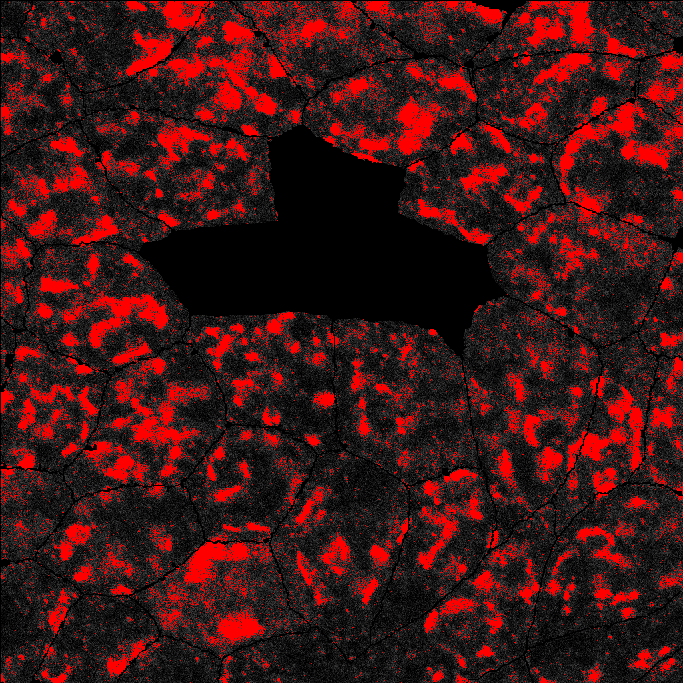

%% Select one image
i = 4;
% Import TGN image
warning('off','all')
ImageDataStore = datastore(files{i,1},'ReadFcn',@imfinfo);
data = readall(ImageDataStore);
image_w = data{1,1}.Width;
image_h = data{1,1}.Height;
BitDepth = data{1,1}.BitDepth;
if BitDepth == 8
    image_j = zeros(image_h,image_w,'uint8');
elseif BitDepth == 16
    image_j = zeros(image_h,image_w,'uint16');
else
    image_j = zeros(image_h,image_w,'double');
end
tstack  = Tiff(files{i,1},'r'); % read tiff file from pathway
image_j  = tstack.read(); % creates empty matrix with the image properties
%% Cell ROI filtering
numPolygon = length(cell_rois{i});
vertices = cell(1,numPolygon);
for r = 1:numPolygon
    vertices{1,r} = cell_rois{i}{1,r};
end
roilabelID = 1:numPolygon;
binary_roi = poly2label(vertices,roilabelID,[image_h,image_w]);
binary_roi = repmat(binary_roi,1,1);
binary_roi = logical(binary_roi)';
image_j = imadjust(image_j); %adjustes intensity range
image_j = uint8(image_j/256);
image_j(binary_roi==0) = 0;

%% Select Threshold
th =[70,256];
%% Binary image
binary = image_j >= th(1,1) & image_j <= th(1,2);
%% Colored image
redChannel = image_j;
greenChannel = image_j;
blueChannel = image_j;
redChannel(binary) = 256;
greenChannel(binary) = 0;
blueChannel(binary) = 0;
% Concatenate r, g, and b channels to form RGB image
rgbImage = cat(3, redChannel, greenChannel, blueChannel);
%% Represent
imshow(rgbImage(:,:,:))

%clearvars -except files n_img th

## Make TGN Mask

n_sets = height(files);
boundaries = cell(1,n_sets);
for i = 1:n_sets %For each set of 3 images
    numPolygon = length(cell_rois{i}); %number of selected cells per image
    if numPolygon > 0
        %% Import the TGN image of each set
        warning('off','all')
        ImageDataStore = datastore(files{i,1},'ReadFcn',@imfinfo);
        data = readall(ImageDataStore);
        image_w = data{1,1}.Width;
        image_h = data{1,1}.Height;
        BitDepth = data{1,1}.BitDepth;
        if BitDepth == 8
            image = zeros(image_h,image_w,'uint8');
        elseif BitDepth == 16
            image = zeros(image_h,image_w,'uint16');
        else
            image = zeros(image_h,image_w,'double');
        end
        tstack  = Tiff(files{i,1},'r'); % read tiff file from pathway
        image(:,:)  = tstack.read(); % creates empty matrix with the image properties
        warning('on','all')
        image = imadjust(image); %adjustes intensity range
        image = uint8(image/256);
        image = imgaussfilt(image,2); %gaussian filter applied
        %% Cell ROI filtering
        for j = 1:width(cell_rois{1,i}) %for each cell
            vertices = cell(1,1);
            vertices{1} = cell_rois{1,i}{1,j};
            binary_roi = poly2label(vertices,1,[image_h,image_w]);
            binary_roi = repmat(binary_roi,1,1);
            binary_roi = logical(binary_roi)';
            image_j = image;
            image_j(binary_roi==0) = 0;
            %% TGN region extraction
            [h,w,f] = size(image_j);
            binary = image_j >= th(1,1) & image_j <= th(1,2); 
            image_j(binary == 0) = 0;
            boundaries_j = cell(0,0);
            areas = cell(0,0);
            boundary = bwboundaries(binary(:,:),'noholes');
            if ~isempty(boundary) == 1
                for k = 1:length(boundary)
                    area = polyarea(boundary{k,1}(:,1),boundary{k,1}(:,2));
                    if area > 10
                        boundaries_j = [boundaries_j;boundary{k,1}];
                        areas = [areas,area];
                    end
                end
                n_roi = size(boundaries_j,1);
                if ~isempty(boundaries_j) == 1
                    L = poly2label(boundaries_j(:,:),[1:n_roi],[w,h]);
                    %I2 = labeloverlay(image_j(:,:),L','Colormap','hsv');
                    L(L ~= 0); %label matrix
                    boundaries_j(:,2) = areas;
                    cell_rois{1,i}{3,j} = boundaries_j;
                    cell_rois{1,i}{4,j} = L;
                    areas = cell2mat(areas);
                    areas = sum(areas,'all');
                    cell_rois{1,i}{5,j} = areas;
                end
            end
        end
    end
end
clearvars -except files n_img n_sets th cell_rois

Example: 

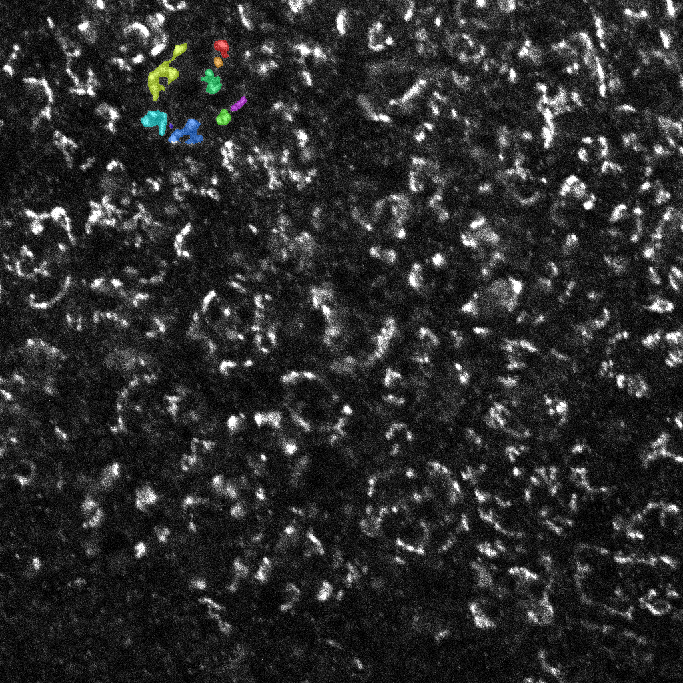

i = 3; %image
%% Import the TGN image of each set
warning('off','all')
ImageDataStore = datastore(files{i,1},'ReadFcn',@imfinfo);
data = readall(ImageDataStore);
image_w = data{1,1}.Width;
image_h = data{1,1}.Height;
BitDepth = data{1,1}.BitDepth;
if BitDepth == 8
    image = zeros(image_h,image_w,'uint8');
elseif BitDepth == 16
    image = zeros(image_h,image_w,'uint16');
else
    image = zeros(image_h,image_w,'double');
end
tstack  = Tiff(files{i,1},'r'); % read tiff file from pathway
image(:,:)  = tstack.read(); % creates empty matrix with the image properties
warning('on','all')
image = imadjust(image); %adjustes intensity range
image = uint8(image/256);
%% Import label matrix previously built
vertices = cell(1,width(cell_rois{i}{3,16}));
for j = 1:length(cell_rois{i}{3,16})
    vertices{1,j} = cell_rois{1,i}{3,16}{j,1};
end
n_roi = width(vertices);
L = poly2label(vertices,[1:n_roi],[image_w,image_h]);
I2 = labeloverlay(image(:,:),L','Colormap','hsv');
imshow(I2)

## Calculate intensities

### Using GM130 mask

This section integrates the intensity inside the TGN regions previously defined, and devides the value by the number of pixels. The average intensity/px in each image is calculated. 

I_ratio = [];
for i = 1:n_sets
    %% Import the TGN image of each set
    warning('off','all')
    ImageDataStore = datastore(files{i,2},'ReadFcn',@imfinfo);
    data = readall(ImageDataStore);
    image_w = data{1,1}.Width;
    image_h = data{1,1}.Height;
    BitDepth = data{1,1}.BitDepth;
    if BitDepth == 8
        image = zeros(image_h,image_w,'uint8');
    elseif BitDepth == 16
        image = zeros(image_h,image_w,'uint16');
    else
        image = zeros(image_h,image_w,'double');
    end
    tstack  = Tiff(files{i,2},'r'); % read tiff file from pathway 
    image(:,:)  = tstack.read(); % creates empty matrix with the image properties
    image_g(:,:) = image(:,:); %Golgi image
    tstack  = Tiff(files{i,3},'r'); % read tiff file from pathway
    image_PM(:,:)  = tstack.read(); % PM image
    %% Calculate intensities per cell
    n_cells = width(cell_rois{1,i});
    for j = 1:n_cells
        %Cell ROI filtering
        vertices = cell(1,1);
        vertices{1,1} = cell_rois{1,i}{1,j};
        binary_roi = poly2label(vertices,1,[image_h,image_w]);
        binary_roi = repmat(binary_roi,1,1);
        binary_roi = logical(binary_roi)';
        i_PM = image_PM;
        i_g = image_g;
        i_PM(binary_roi==0) = 0; %selection of single cell
        i_g(binary_roi==0) = 0;
        %PM intensity
        I_PM = sum(i_PM,'all'); %total intensity
        nI_PM = I_PM/cell_rois{1,i}{2,j}; %intensity per px
        %Golgi intensity
        if ~isempty(cell_rois{1,i}{3,j}) %if there is GM130 roi
            L = cell_rois{1,i}{4,j}'; %label matrix with the TGN region
            i_g(L==0) = 0; %only selected GM130 region in the golgi channel
            I_G = sum(i_g,'all'); %total intensity
            nI_G = I_G/cell_rois{1,i}{5,j}; %intensity/px
            I = [nI_G,nI_PM];
            I_ratio = [I_ratio;I];
        end
    end
end
clearvars -except cell_rois files n_img n_sets I_ratio

### Without GM130 mask

I_ratio = [];
for i = 1:n_sets
    %% Import the TGN image of each set
    warning('off','all')
    ImageDataStore = datastore(files{i,2},'ReadFcn',@imfinfo);
    data = readall(ImageDataStore);
    image_w = data{1,1}.Width;
    image_h = data{1,1}.Height;
    BitDepth = data{1,1}.BitDepth;
    if BitDepth == 8
        image = zeros(image_h,image_w,'uint8');
    elseif BitDepth == 16
        image = zeros(image_h,image_w,'uint16');
    else
        image = zeros(image_h,image_w,'double');
    end
    tstack  = Tiff(files{i,2},'r'); % read tiff file from pathway 
    image(:,:)  = tstack.read(); % creates empty matrix with the image properties
    image_g(:,:) = image(:,:); %Golgi image
    tstack  = Tiff(files{i,3},'r'); % read tiff file from pathway
    image_PM(:,:)  = tstack.read(); % PM image
    %% Calculate intensities per cell
    n_cells = width(cell_rois{1,i});
    for j = 1:n_cells
        %Cell ROI filtering
        vertices = cell(1,1);
        vertices{1,1} = cell_rois{1,i}{1,j};
        binary_roi = poly2label(vertices,1,[image_h,image_w]);
        binary_roi = repmat(binary_roi,1,1);
        binary_roi = logical(binary_roi)';
        i_PM = image_PM;
        i_g = image_g;
        i_PM(binary_roi==0) = 0; %selection of single cell
        i_g(binary_roi==0) = 0;
        %PM intensity
        I_PM = sum(i_PM,'all'); %total intensity
        nI_PM = I_PM/cell_rois{1,i}{2,j}; %intensity per px
        %Golgi intensity
        I_G = sum(i_g,'all'); %total intensity
        nI_G = I_G/cell_rois{1,i}{2,j}; %intensity per px
        I = [nI_G,nI_PM];
        I_ratio = [I_ratio;I];
    end
end
clearvars -except cell_rois files n_img n_sets I_ratio